clear all
%f=figure(1);
R=[0.1402 0.3624 0.5714 1.3378];
%R1=[0 0 0 0 0 0 0 0]
noise=[1e-7 1e-6 1e-5 1e-4]

noise = 1.0e-04 *

    0.0010    0.0100    0.1000    1.0000


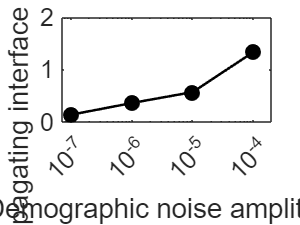

%D=linspace(10000,50000,5);
%Biomass_CarryingCap=1e-7*[6.56 6.1 5.788 5.615 5.51 1.0];
x=noise;
%x=D;
%x0=[0.005 0.005 0.02 0.02]
%y0=[0 4 4 0]
%c=[1 1 2 2]
%R(end) = NaN;
%x(7) = 0.02;
%c=R;
f=figure();
%patch(x,R,c,'EdgeColor','interp','Marker','o','MarkerFaceColor','flat')
%patch(x,R,c)
%colorbar;
semilogx(x,R,'ko-','LineWidth',1.5,'MarkerSize',8,'MarkerFaceColor','black')
%hold on 
%plot(0.2:0.4:3.0,R1,'s-')
xlim([7e-8 2e-4])
ylim([0 2.0])
xlabel('Demographic noise amplitude')
ylabel('Propagating interface roughness')
%x=[0.005 0.005 0.02 0.02]
%y=[0 4 4 0]
%c=[1 1 2 2]
%patch(x,y,c)
%legend('k=1','k=0')
%xBox = [0, 2.6, 2.6, 0]
%yBox = [0, 0, 12, 12]
%patch(xBox, yBox, 'black', 'FaceColor', [66, 129, 164]/255, 'FaceAlpha', 0.7);
%xBox = [2.6, 4.0, 4.0, 2.6]
%yBox = [0, 0, 12, 12]
%patch(xBox, yBox, 'black', 'FaceColor', [0.6350 0.0780 0.0840], 'FaceAlpha', 0.7);
text(0.006,1.8,'furcated','FontSize',15, "Color",[1 1 0]);
text(0.018,1.8, 'smooth','FontSize',15, "Color", [0 0 1] );
%set(gca,'FontSize',14)
%hold off;
set(gca, 'XTick', [1e-7 1e-6 1e-5 1e-4])
set(gca, 'FontSize', 15)

box on

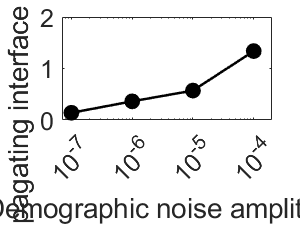

exportgraphics(f,'RvsSigma.png')